## **Part 1 : System Identification**

You are given a virtual plant as a Simscape model. The input to the plant is voltage from the controller, and the outputs from the plant are angular position  and angular velocity.

Write a thorough, yet concise report on methods of identify the following properties and characteristics

- Open-loop Poles/Zeros

- Transfer Function(s)

- State-space Model

- Settling time and Percent Overshoot

### Author

- Kantaka    Sirithanarattanakul    ID : 62340500002

- Keedita     Chaihetphon              ID : 62340500003

- Pakapak   Silpapinun                  ID : 62340500042

**Date **: 24 June 2021


$$\begin{array}{l}
R:\textrm{Resistance}\;\left(\Omega \right)\\
L:\textrm{Inductance}\;\left(H\right)\\
i:\textrm{Current}\;\left(A\right)\\
\omega_{\textrm{in}} :\textrm{Rotor}\;\textrm{velocity}\;\left(\textrm{rad}/s\right)\\
T_{\textrm{in}} :\textrm{Rotor}\;\textrm{torque}\;\left(N\cdot m\right)\\
K_b :\textrm{Back}\;\textrm{emf}\;\textrm{constant}\\
K_m :\textrm{Motor}\;\textrm{torque}\;\textrm{constant}\\
J_m :\textrm{Rotor}\;\textrm{inertia}\;\left(\textrm{Kg}\cdot m^2 \right)\\
B_m :\textrm{Rotor}\;\textrm{damping}\;\left(N\cdot m/\left(\textrm{rad}/s\right)\right)\\
\eta :\textrm{Gear}\;\textrm{ratio}\\
J_c :\textrm{Inertia}\;\textrm{in}\;\textrm{axis}\;\left(\textrm{Kg}\cdot m^2 \right)\\
B_c :\textrm{Damping}\;\textrm{in}\;\textrm{axis}\;\left(N\cdot m/\left(\textrm{rad}/s\right)\right)
\end{array}$$


Circuit :


$$V_{\textrm{in}} \left(t\right)=R\cdot i\;+L$$

$$\frac{\mathrm{d}}{\mathrm{d}t}i+K_b \;\omega_{\textrm{in}}$$


Laplace transform :


$$V_{\textrm{in}} \left(s\right)=\left(R+L\right)I\left(s\right)+K_b \;\Omega_{\textrm{in}} \left(s\right)$$


Motor's dynamics :


$$J_m \dot{{\;\;\omega }_{\textrm{in}} } =K_m \;i-B_m \;\omega_{\textrm{in}} -T_{\textrm{in}}$$


Laplace transform :


$$J_m \;s{\;\Omega }_{\textrm{in}} \left(s\right)=K_m \;I\left(s\right)-B_m \;\Omega_{\textrm{in}} \left(s\right)-T_{\textrm{in}} \left(s\right)$$


Gearbox :


$$\eta =\frac{T_{\textrm{out}} }{T_{\textrm{in}} }=\frac{\Omega_{\textrm{in}} }{\Omega_{\textrm{out}} }$$


After gearbox :


$$\dot{{J_c \;\omega }_{\textrm{out}} } =T_{\textrm{out}} -B_c \;\omega_{\textrm{out}}$$


Laplace transform :


$$J_c \;\Omega_{\textrm{out}} \left(s\right)=T_{\textrm{out}} \left(s\right)-B_c \;\Omega_{\textrm{out}} \left(s\right)$$


Assembly :


$$T\left(s\right)\;=\;\frac{\Omega_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\;\frac{K_m }{\left(J_m \eta L+\frac{J_c L}{\eta }\right)s^2 +\left(J_m \eta R+B_m \eta L+\frac{J_c R+B_c L}{\eta }\right)s+\left(B_m \eta R+\frac{B_c R}{\eta }+{K_m K}_b \eta \right)}$$


and write in form that


$$\begin{array}{l}
T\left(s\right)\;=\;\frac{K}{{\mathrm{As}}^2 +\mathrm{Bs}+C}\\
T\left(s\right)\;=\;\frac{\frac{K}{A}}{s^2 +\frac{B}{A}s+\frac{C}{A}}\\
T\left(s\right)\;=\;\frac{k}{s^2 +2\zeta \omega_n s+\omega_n^2 }
\end{array}$$


format long
syms Km Kb Jm Jc Bm Bc nm L R

% Ajarn's physical parameters
Jm  = 0.01e-7;
Jc  = 0.1;
Bm  = 0;
Bc  = 0.01;
nm  = 64;
L   = 65e-6;
R   = 0.39;
% Motor velocity constant
Kv  = (8100 *2*pi/60) / 12; % (No-load speed / Peak voltage)
% back-EMF constant
Kb  = 1 / Kv;
% Motor torque constant
Km  = 1 / Kv;

% Calculation
K   = Km;
A   = Jm*nm*L + Jc*L/nm;
B   = Jm*nm*R + Bm*nm*L + (Jc*R + Bc*L)/nm;
C   = Bm*nm*R + Bc*R/nm + Km*Kb*nm;

% Transfer function by calculation
TF_Omega_Calculation = tf(K/A, [1 B/A C/A])

We got transfer function of voltage and angular velocity :


$$T\left(s\right)\;=\;\frac{\Omega \left(s\right)}{V_{\mathrm{in}} \left(s\right)}\;=\;\frac{1\ldotp 393\cdot {10}^5 }{s^2 +6000s+1\ldotp 267\cdot {10}^5 }$$


and transfer function of voltage and angular position :


$$\Omega \left(s\right)\;=\;s\cdot \Theta \left(s\right)$$



$$\frac{\Theta \left(s\right)}{V_{\mathrm{in}} \left(s\right)}\;=\;\frac{1\ldotp 393\cdot {10}^5 }{s^3 +6000s^2 +\left(1\ldotp 267\cdot {10}^5 \right)s}$$


compare our calculation with Unicorn Physical System :

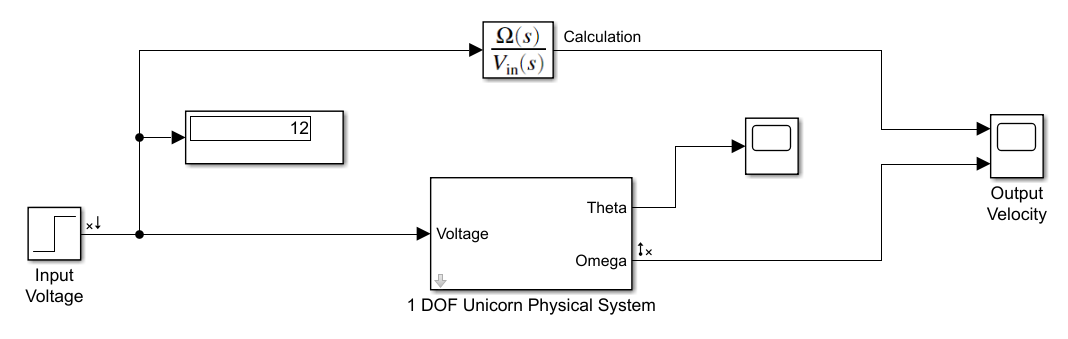

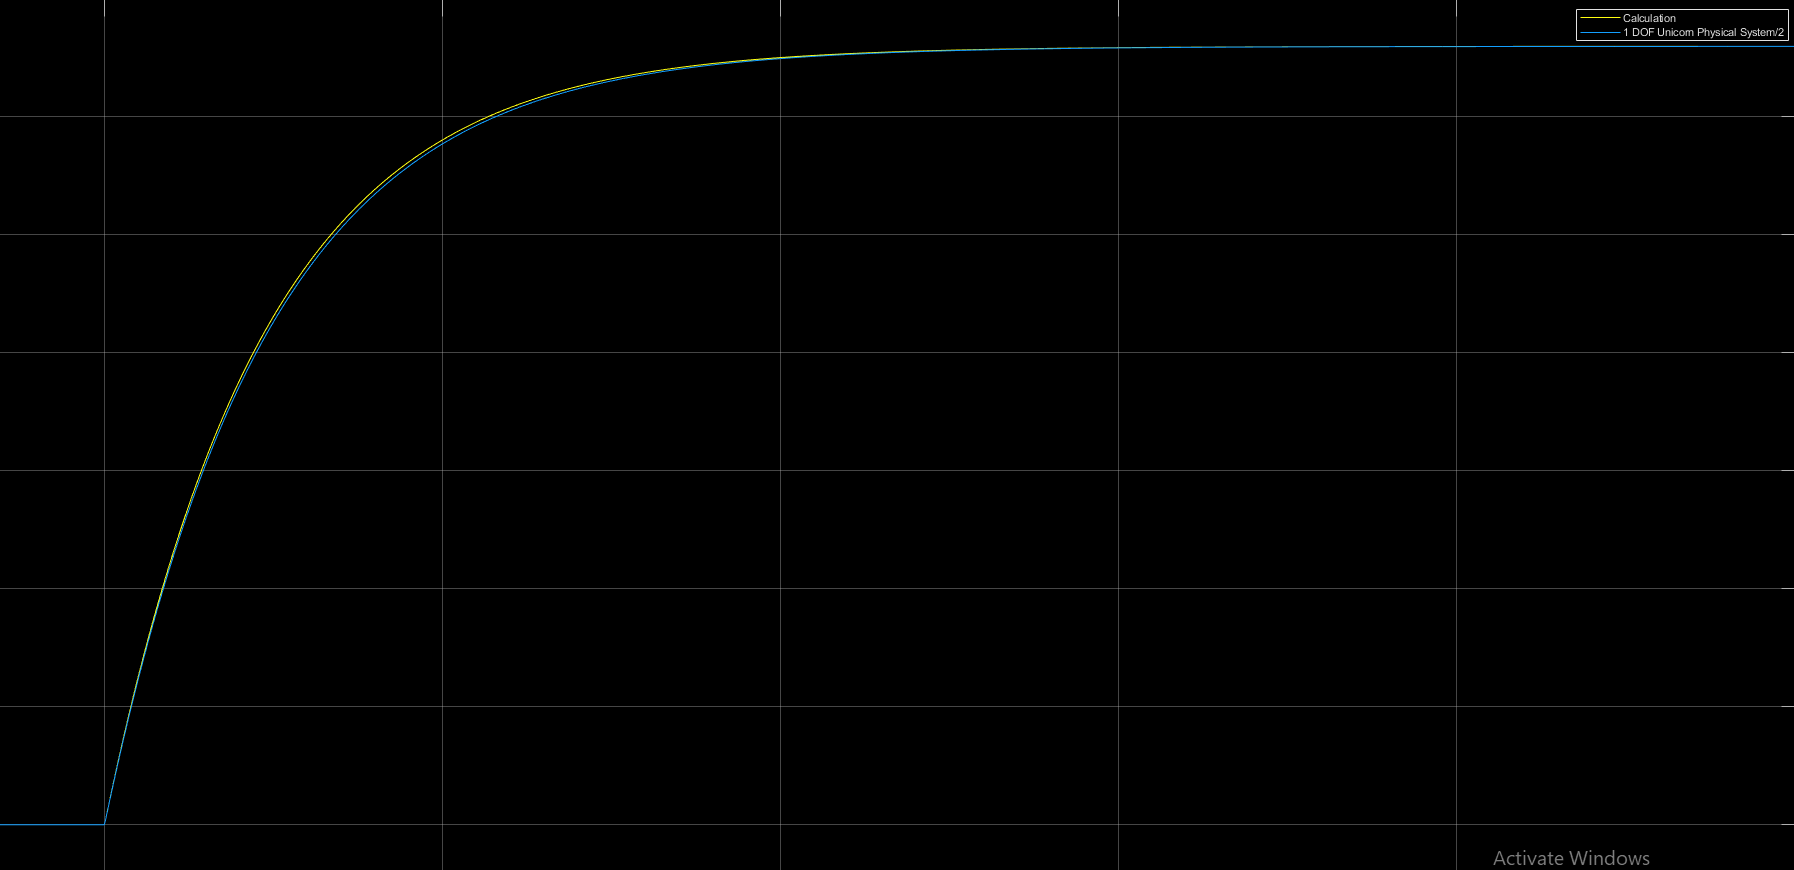

(Output Velocity Compare)

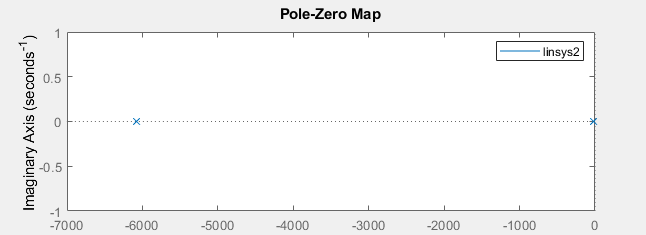

# **(NOT USE)**

so we got the static gain constant :


$$k\;=\;1\ldotp 359\cdot {10}^5$$


and natural frequency :


$$\omega_n \;=\sqrt{1\ldotp 264\cdot {10}^5 }\approx 355\ldotp 528$$


and the damping ratio :


$$\zeta \;=\;\frac{6103}{2\cdot 355\ldotp 527}\approx \;8\ldotp 583$$


% Transfer function by Model Linearizer
tf(Omega_ModelLinearizer)

TF_Omega_Calculation =
 
         1.393e05
  -----------------------
  s^2 + 6000 s + 1.267e05
 
Continuous-time transfer function.




% Solve the equations find Km, Kb, R
%====================================================================================================================
%EQN = [K/A == 1.389e05, B/A == 6103, C/A == 1.264e05];
%VAR = [Km, Kb, R];
%[Km_solve, Kb_solve, R_solve] = solve(EQN, VAR);
%vpa(Km_solve, 10)  % got Km = 0.01410760907
%vpa(Kb_solve, 10)  % got Kb = 0.01414337513
%vpa(R_solve, 10)   % got R  = 0.3968878528
%====================================================================================================================

% DC motor default parameters
Km  = 6.876e-4;
Kb  = 6.876e-4;
Jm  = 0.01e-7;
Jc  = 0.1;
Bm  = 0;
Bc  = 0.01;
nm  = 64;
L   = 12e-6;
R   = 3.9;

% Calculation
K   = Km;
A   = Jm*nm*L + Jc*L/nm;
B   = Jm*nm*R + Bm*nm*L + (Jc*R + Bc*L)/nm;
C   = Bm*nm*R + Bc*R/nm + Km*Kb*nm;

% Transfer function by calculation
tf(K/A, [1 B/A C/A])
% Transfer function by Model Linearizer
tf(Omega_ModelLinearizer_default)